close_system('all', 0);

modelName = 'dsp_model';

if ~bdIsLoaded(modelName)
    load_system(modelName);
end

close all;

N = 1000000

N = 1000000

SNR_range = [-7 4]

SNR_range =     -7     4


SNR = SNR_range(1):1:SNR_range(2);
Ts = 1e-6

Ts = 1.0000e-06

StopTime = N*Ts

StopTime = 1

t = (0:N-1)' * Ts;
bitsIn = randi([0 1], N, 1);
txData = [t, bitsIn];

BER_results_QPSK = zeros(size(SNR));
BER_results_BPSK = zeros(size(SNR));
for i = 1:length(SNR)
    SNR_temp = SNR(i);
    out = sim(modelName, 'StopTime', num2str(StopTime));
    bitsOut_QPSK = out.rxData_QPSK;
    bitsOut_BPSK = out.rxData_BPSK;
    BER_results_QPSK(i) = sum(bitsIn ~= bitsOut_QPSK(3:length(bitsIn)+2)) / N;
    BER_results_BPSK(i) = sum(bitsIn ~= bitsOut_BPSK(1:length(bitsIn))) / N;
end  

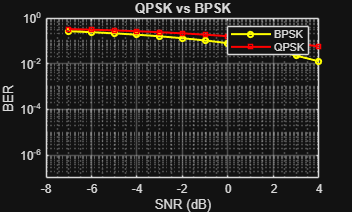

figure;

semilogy(SNR, BER_results_BPSK, 'yo-', 'LineWidth', 1.5, 'MarkerSize', 4, 'DisplayName', 'BPSK');
hold on;
semilogy(SNR, BER_results_QPSK, 'rs-', 'LineWidth', 1.5, 'MarkerSize', 4, 'DisplayName', 'QPSK');


set(gca, 'YScale', 'log');


ylim([1e-7 1]);


grid on;
set(gca, 'YMinorGrid', 'on');
set(gca, 'XMinorGrid', 'on');


xlabel('SNR (dB)');
ylabel('BER');
title('QPSK vs BPSK');
legend('show');